## 5.

caso 4 motores

p = rand(1);
n = 4;

k = 1:4;
distribuicao = zeros(1,length(k));

for i = 1:length(k)
    %calcular coeficiente
    choose = factorial(n)/(factorial(k(i))*factorial(n-k(i)));
    %prob
    probabilidade_t = choose * (p^k(i)) * ((1-p)^(n-k(i)));
    distribuicao(i) = probabilidade_t;

end

fprintf('Probabiliade falha: \n 1 motor: %.3f\n 2 motores: %.3f\n 3 motores: %.3f \n 4 motores: %.3f\n Total = %.3f \n Pobabiliade despenho = %.3f', distribuicao, sum(distribuicao), sum(distribuicao(3:4)));

Probabiliade falha: 
 1 motor: 0.060
 2 motores: 0.237
 3 motores: 0.419 
 4 motores: 0.278
 Total = 0.994 
 Pobabiliade despenho = 0.698

caso 2 motores

n = 2;
k = 1:2;
distribuicao_2 = zeros(1,length(k));

for i = 1:length(k)
    %calcular coeficiente
    choose = factorial(n)/(factorial(k(i))*factorial(n-k(i)));
    %prob
    probabilidade_t = choose * (p^k(i)) * ((1-p)^(n-k(i)));
    distribuicao_2(i) = probabilidade_t;

end

fprintf('Probabiliade falha: \n 1 motor: %.3f\n 2 motores: %.3f\n Total = %.3f \n Pobabiliade despenho = %.3f', distribuicao_2, sum(distribuicao_2), sum(distribuicao_2(2)));

Probabiliade falha: 
 1 motor: 0.398
 2 motores: 0.527
 Total = 0.925 
 Pobabiliade despenho = 0.527

Simular para descobrir qual o melhor sem saber P(falha do motor)

N = 1e5;
quatro = 0;
dois = 0;
prob = 0:0.01:0;

for j = 1:N
    p = rand(1);
    n = 4;
    
    k = 1:4;
    distribuicao = zeros(1,length(k));
    
    for i = 1:length(k)
        %calcular coeficiente
        choose = nchoosek(n, k(i));
        
        %prob
        probabilidade_t = choose * (p^k(i)) * ((1-p)^(n-k(i)));
        distribuicao(i) = probabilidade_t;
    
    end

    n = 2;
    k = 1:2;
    distribuicao_2 = zeros(1,length(k));
    
    for i = 1:length(k)
        %calcular coeficiente
        choose = nchoosek(n, k(i));
        %prob
        probabilidade_t = choose * (p^k(i)) * ((1-p)^(n-k(i)));
        distribuicao_2(i) = probabilidade_t;
    
    end

    % Calcule as probabilidades de despenho
    desempenho_4 = sum(distribuicao(3:4));
    desempenho_2 = distribuicao_2(2);

    % Compare as probabilidades de desempenho
    if desempenho_4 > desempenho_2
        quatro = quatro + 1;
    else
        dois = dois + 1;
    end
end

dois

dois = 33370

quatro

quatro = 66630


if dois > quatro 
    fprintf('Sem saber a probabilidade');
    fprintf('É preferível voar num avião com 4 motores');
else
    fprintf('Sem saber a probabilidade');
    fprintf('É preferível voar num avião com 2 motores');
end

Sem saber a probabilidade

É preferível voar num avião com 2 motores

Gráfico ao longo da probabilidade

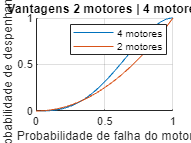

p = 0:0.001:1;

dis_graf_4 = zeros(1, length(p));
dis_graf_2 = zeros(1, length(p));

n = 4; % 4 tentativas
j = 4; % possíveis resultados
%escrevi j para pode usar k nos loops
prob_4 = zeros(1, j);

n_2 = 2;
j_2 = 2;
prob_2 = zeros(1, j_2);

for i = 1:length(p)
    for k = 1:j
        prob_t = nchoosek(n, k) * p(i)^k * (1 - p(i))^(n - k);
        prob_4(k) = prob_t;
    end

    dis_graf_4(i) = sum(prob_4(3:4));

    for k = 1:j_2
        prob_t = nchoosek(n_2, k) * p(i)^k * (1 - p(i))^(n_2 - k);
        prob_2(k) = prob_t;
    end

    dis_graf_2(i) = prob_2(2);
end

hold on;
plot(p, dis_graf_4);
plot(p, dis_graf_2);
grid on;
title('Vantagens 2 motores | 4 motores');
legend('4 motores', '2 motores');
xlabel('Probabilidade de falha do motor');
ylabel('Probabilidade de despenhamento');